# **Workshop** - Slider Crank Model Parameters

*This script defines all the parameters needed to run the workshop_slider_crank.slx model.*

Consider the slider crank mechanism shown in **Figure 1** below. For the configuration shown in **Figure 1a**, determine:

- $v_B$ the velocity of piston $B$

- $\omega_{\textrm{AB}}$ the angular velocity of rod$\textrm{AB}$

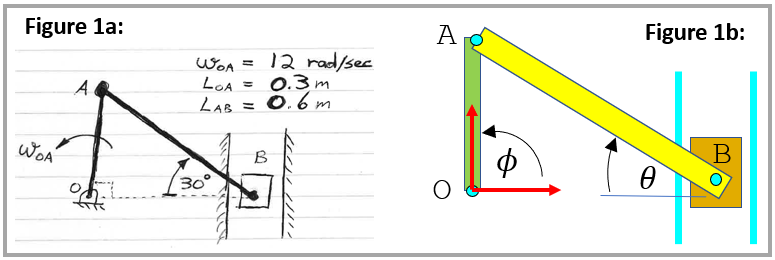

Let's define some MATLAB variables that characterise the system shown in **Figure 1a **and** Figure 1b:**

phi_rad             = deg2rad(90);  % (rad)
theta_rad           = deg2rad(30);  % (rad)
phi_dot_rad_per_sec = 12;           % (rad/sec)
omega_OA            = phi_dot_rad_per_sec;

L_OA       = 0.3;                   % (m)
L_AB       = 0.6;                   % (m) 
L_OB       = L_AB * cos(theta_rad); % (m)

## Start a new Simscape™ Multibody™ model 

Let's open a blank Simscape Multibody model template with commonly used blocks 

model = smnew('workshop_slider_blank');

model = 360.0018

activeConfigObj = getActiveConfigSet(model);
tStop=0.7;
set_param(activeConfigObj,'StopTime','tStop');